%==========================================================================
% Author:    Naghmeh Akhavan (N. Akhavan)
% Affil.:    University of Michigan
% Contact:   nakhavan@umich.edu
%
% Summary:
%   Mouse & Rat (Light/Dark): compute the occurrence rate of "sequential" REM
%   cycles as a function of REM propensity, using BASE CSV cycle tables and
%   a consistent long-wake exclusion (DROP ≥ 2 min).
%
% Key definitions:
%   1) Long-wake DROP (per cycle):
%      - Prefer MaxWake* columns (longest single Wake block inside IREM).
%      - If missing, fallback to total Wake within IREM ≥ 2 min (proxy).
%
%   2) Propensity P(t,Δ):
%      - Fit a 2-component Gaussian mixture model (GMM) to z = log(NREM_sec),
%        pooled across all kept cycles in the dataset (toolbox-free EM).
%      - Let F(t) be the resulting CDF of NREM duration (in seconds). Then
%
%           P(t,Δ) = [F(t+Δ) − F(t)] / [1 − F(t)] ,  Δ = DELTA_SEC.
%
%      - Here, propensity is evaluated at each cycle's REMpost onset time,
%        using t = NREM_sec for that cycle.
%
%   3) Increasing-zone window (fixed, per dataset):
%      - Restrict analysis to cycles whose NREM duration lies within the
%        precomputed window WIN.(Species).(Phase) = [tMin_s, tMax_s] seconds.
%        (These windows were computed elsewhere as: global min of P(t,Δ) to
%         first local max after that min.)
%
%   4) Sequential REMpost:
%      - A cycle is "sequential" if the NEXT inter-REM duration (IREM_next)
%        for the same subject is ≤ SEQ_THRESH_SEC (default 2 minutes).
%      - IREM_next is assigned by sorting cycles within each subject using an
%        approximate "episode clock" derived from (REMpre + IREM).
%
% Outputs:
%   - For each of 4 datasets (Mouse/Rat × Light/Dark):
%       A bar plot of sequential occurrence rate vs propensity (increasing zone),
%       with per-bin sample sizes annotated as n=...
%   - Console printout: usable sample size and overall sequential rate in-zone.
%
% Inputs:
%   - BASE CSV tables (one per dataset) containing cycle-level metrics such as
%     NREM, IREM, REMpre, REMpost, Wake/Movement, and optionally MaxWake*.
%
% Last updated: 2026-01-19
%==========================================================================


clear; clc; close all;


## Paths

mouseLightCSV = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Mouse DATA\Mouse light data-Naghmeh\BigResultTable_mouse_light.csv";
mouseDarkCSV  = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Mouse DATA\Mouse dark data-Naghmeh\BigResultTable_mouse_dark.csv";
ratLightCSV   = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Rat DATA\Rat light data-Naghmeh\BigResultTable_rat_light.csv";
ratDarkCSV    = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Rat DATA\Rat dark data-Naghmeh\BigResultTable_rat_dark.csv";


## Long-wake filter (DROP)

WAKE_BREAK_MIN = 2;                       % minutes
WAKE_BREAK_SEC = WAKE_BREAK_MIN * 60;     % seconds


## Fixed increasing-zone windows

WIN.Mouse.Light = [123 618];
WIN.Mouse.Dark  = [ 88 597];
WIN.Rat.Light   = [ 93 331];
WIN.Rat.Dark    = [ 87 291];


## Knobs

DELTA_SEC       = 30;       % propensity horizon
SEQ_THRESH_MIN  = 2;        % "sequential" threshold (next IREM <= this)
SEQ_THRESH_SEC  = SEQ_THRESH_MIN*60;
NBINS_PROP      = 10;       % bars for rate panel

% Colors
mouseCol = [0.55 0.27 0.68];   % purple
ratCol   = [0.90 0.50 0.10];   % orange


## Run four datasets

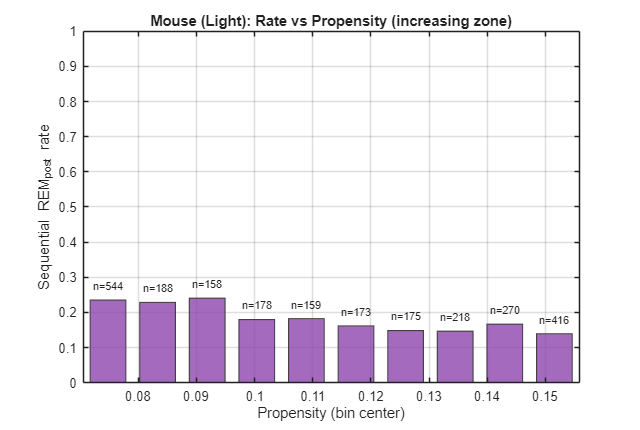

Mouse (Light): in-zone usable n=2479 | overall sequential rate = 0.185


run_one(mouseLightCSV, "Mouse", "Light", WIN.Mouse.Light, mouseCol, ...
        DELTA_SEC, SEQ_THRESH_SEC, NBINS_PROP, WAKE_BREAK_SEC, WAKE_BREAK_MIN);

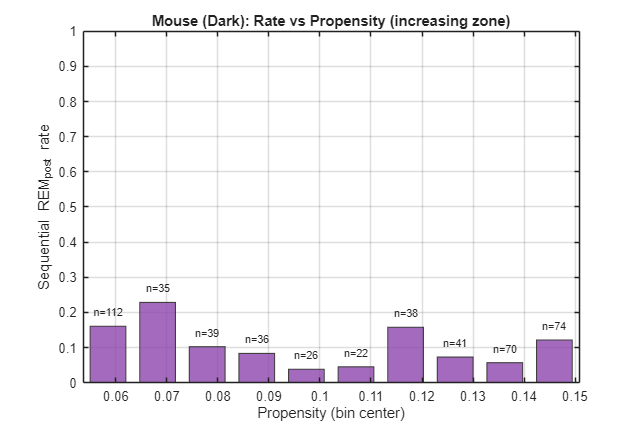

Mouse (Dark): in-zone usable n=493 | overall sequential rate = 0.116


run_one(mouseDarkCSV,  "Mouse", "Dark",  WIN.Mouse.Dark,  mouseCol, ...
        DELTA_SEC, SEQ_THRESH_SEC, NBINS_PROP, WAKE_BREAK_SEC, WAKE_BREAK_MIN);

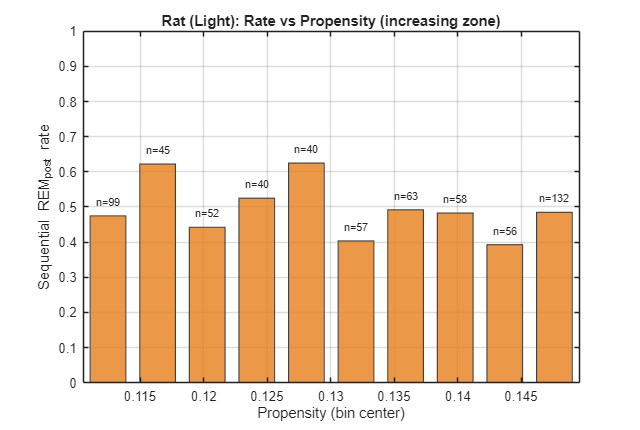

Rat (Light): in-zone usable n=642 | overall sequential rate = 0.486


run_one(ratLightCSV,   "Rat",   "Light", WIN.Rat.Light,   ratCol,   ...
        DELTA_SEC, SEQ_THRESH_SEC, NBINS_PROP, WAKE_BREAK_SEC, WAKE_BREAK_MIN);

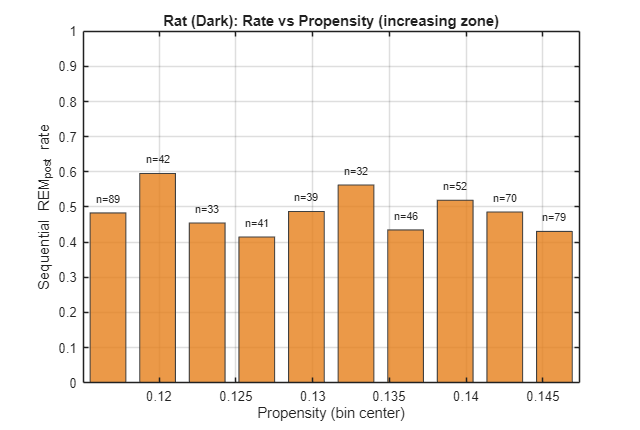

Rat (Dark): in-zone usable n=523 | overall sequential rate = 0.482


run_one(ratDarkCSV,    "Rat",   "Dark",  WIN.Rat.Dark,    ratCol,   ...
        DELTA_SEC, SEQ_THRESH_SEC, NBINS_PROP, WAKE_BREAK_SEC, WAKE_BREAK_MIN);


fprintf("All done.\n");

All done.


## Function

function run_one(csvPath, species, phase, winSec, curveColor, ...
                 DELTA_SEC, SEQ_THRESH_SEC, NBINS_PROP, WAKE_BREAK_SEC, WAKE_BREAK_MIN)

    assert(isfile(csvPath), 'CSV not found: %s', csvPath);
    R = readtable(csvPath, 'TextType','string');

    % Normalize/ensure columns
    need = ["Subject_Index","REM_Cycle_Index","REMpre","NREM","IREM","Wake","Movement","REMpost"];
    for v = need
        if ~ismember(v, string(R.Properties.VariableNames)), R.(v) = NaN(height(R),1); end
    end
    R.Subject_Index   = string(R.Subject_Index);
    R.REM_Cycle_Index = string(R.REM_Cycle_Index);
    R.REMpre   = double(R.REMpre);     % sec
    R.NREM     = double(R.NREM);       % sec
    R.IREM     = double(R.IREM);       % sec
    R.REMpost  = double(R.REMpost);    % sec
    R.Wake     = double(R.Wake);
    R.Movement = double(R.Movement);

    % Rebuild IREM if missing
    if (~ismember("IREM", string(R.Properties.VariableNames))) || all(isnan(R.IREM))
        if all(ismember(["NREM","Wake","Movement"], string(R.Properties.VariableNames)))
            R.IREM = R.NREM + R.Wake + R.Movement;
        end
    end

    % Long-wake filtering (prefer MaxWake*, else fallback: total Wake in IREM)
    vn = string(R.Properties.VariableNames);
    maxWakeCandidates = ["MaxWakeSec","MaxWake_s","MaxWakeInIREMSec","MaxWakeInIREM_s","MaxWakeBlockSec","MaxWakeBlock_s"];
    if any(ismember(maxWakeCandidates, vn))
        cname = maxWakeCandidates(find(ismember(maxWakeCandidates, vn), 1, 'first'));
        maxWakeSec = double(R.(cname));
        dropFlag = isfinite(maxWakeSec) & (maxWakeSec >= WAKE_BREAK_SEC);
    elseif ismember("Wake", vn)
        dropFlag = isfinite(R.Wake) & (R.Wake >= WAKE_BREAK_SEC);  % fallback
    else
        dropFlag = false(height(R),1);
        warning('No MaxWake* or Wake column in %s; skipping long-wake filtering.', csvPath);
    end
    R = R(~dropFlag, :);

    % Arrays for analysis
    N_all = R.NREM;              % for GMM fit
    mFit  = isfinite(N_all) & N_all>0;
    N_all = N_all(mFit);

    N_s        = R.NREM;
    REMpost_s  = R.REMpost;
    valid_seq  = isfinite(N_s) & N_s>0 & isfinite(REMpost_s) & REMpost_s>0;

    N_s        = N_s(valid_seq);
    REMpost_s  = REMpost_s(valid_seq);
    Subj_v     = R.Subject_Index(valid_seq);
    CyID_v     = R.REM_Cycle_Index(valid_seq);
    REMpre_v   = R.REMpre(valid_seq);
    IREM_v     = R.IREM(valid_seq);

    if isempty(N_all) || isempty(N_s), warning('Insufficient data after filters.'); return; end

    % Fit lumped 2-comp GMM on z = log(NREM sec) [toolbox-free]
    z_all = log(N_all(:)); z_all = z_all(isfinite(z_all));
    [w, mu, sd] = fit_gmm_1d(z_all, 2, struct('nStarts',30,'maxIter',250,'tol',1e-6, ...
        'trimFrac',0.01,'sdMin',0.08,'sdMax',3.0,'clipQuantiles',[0.5 99.5]));
    Phi = @(u) 0.5*(1+erf(u./sqrt(2)));
    Fsec = @(tt) arrayfun(@(x) sum(w .* Phi((log(max(x,eps))-mu)./sd)), tt);

    % Propensity at REMpost onset
    P_onset = ( Fsec(N_s + DELTA_SEC) - Fsec(N_s) ) ./ max(1 - Fsec(N_s), eps);

    % ---- Increasing-zone window (fixed)
    tMin_s = winSec(1); tMax_s = winSec(2);
    inWindow = (N_s >= tMin_s) & (N_s <= tMax_s);

    % Build sequential label (next IREM <= threshold) using episode order
    T = table(Subj_v, CyID_v, N_s, REMpost_s, P_onset, IREM_v, REMpre_v, ...
              'VariableNames',{'Subj','Cycle','N_s','REMpost_s','P_onset','IREM','REMpre'});

    T.IREM_next = NaN(height(T),1);
    [Gsubj, subjKeys] = findgroups(T.Subj);
    for gi = 1:numel(subjKeys)
        idx = find(Gsubj==gi);
        if isempty(idx), continue; end
        dMin  = (T.REMpre(idx) + T.IREM(idx))/60;   % minutes between REM onsets
        dMin(~isfinite(dMin)) = 0;
        cs   = [0; cumsum(dMin)];
        mid  = (cs(1:end-1) + cs(2:end))/2;
        [~, ord] = sort(mid, 'ascend');            % chronological order
        ii = idx(ord);
        if numel(ii) >= 2
            T.IREM_next(ii(1:end-1)) = T.IREM(ii(2:end));
        end
    end

    T.Seq = double(T.IREM_next <= SEQ_THRESH_SEC);
    T.Seq(~isfinite(T.IREM_next)) = NaN;

    % Keep in-window with valid Seq
    mKeep = inWindow & isfinite(T.Seq);
    xSeq  = T.P_onset(mKeep);
    ySeq  = T.Seq(mKeep);

    if isempty(xSeq)
        warning('No usable data in increasing zone for %s (%s).', species, phase);
        return;
    end


## Figure: sequential rate by propensity bins (bars ONLY)

    figure('Color','w','Position',[130 140 640 430], ...
        'Name', sprintf('%s (%s): Occurrence rate vs Propensity (LW ≥ %g min)', species, phase, WAKE_BREAK_MIN));

    edges = linspace(min(xSeq), max(xSeq), NBINS_PROP+1);
    [~,~,bid] = histcounts(xSeq, edges);
    centers = (edges(1:end-1)+edges(2:end))/2;

    rate = nan(1, NBINS_PROP); nbin = zeros(1, NBINS_PROP);
    for b = 1:NBINS_PROP
        m = (bid==b);
        nbin(b) = sum(m);
        if nbin(b)>0, rate(b) = mean(ySeq(m),'omitnan'); end
    end

    barWidth = 0.72;
    h = bar(centers, rate, barWidth, 'FaceAlpha',0.80, ...
        'FaceColor', curveColor, 'EdgeColor',[0.25 0.25 0.25], 'LineWidth',0.8);
    hold on; grid on; box on;
    xlabel('Propensity (bin center)');
    ylabel('Sequential REM_{post} rate');
    title(sprintf('%s (%s): Rate vs Propensity (increasing zone)', species, phase));
    ylim([0 1]); xlim([edges(1) edges(end)]);
    uistack(h,'top');

    for b = 1:NBINS_PROP
        if nbin(b)>0
            text(centers(b), min(rate(b)+0.04,0.98), sprintf('n=%d', nbin(b)), ...
                'HorizontalAlignment','center', 'FontSize', 8);
        end
    end

    fprintf('%s (%s): in-zone usable n=%d | overall sequential rate = %.3f\n', ...
        species, phase, numel(xSeq), mean(ySeq,'omitnan'));
end


## Functions

function [w, mu, sd, info] = fit_gmm_1d(x, K, opts)
    x = x(:); x = x(isfinite(x));
    if nargin<3, opts = struct; end
    g = @(f,d) (isfield(opts,f)&&~isempty(opts.(f))) * opts.(f) + (~isfield(opts,f)||isempty(opts.(f))) * d;
    nStarts  = g('nStarts',30); maxIter = g('maxIter',250); tol = g('tol',1e-6);
    trimFrac = g('trimFrac',0.01); sdMin = g('sdMin',0.08); sdMax = g('sdMax',3.0);
    cq = g('clipQuantiles',[0.5 99.5]); % percent

    qlo = quantile_nontb(x, cq(1)/100); qhi = quantile_nontb(x, cq(2)/100);
    x   = x(x>=qlo & x<=qhi); log2pi = log(2*pi);

    bestLL = -inf; best = [];
    for s=1:nStarts
        q20 = quantile_nontb(x,0.20); q80 = quantile_nontb(x,0.80);
        mu0 = linspace(q20, q80, K) + 0.05*randn(1,K);
        sd0 = max(sdMin, 0.3*std(x))*ones(1,K);
        w0  = ones(1,K)/K;
        [w1, mu1, sd1, LL] = em_core(x, w0, mu0, sd0, maxIter, tol, trimFrac, sdMin, sdMax, log2pi);
        if LL(end) > bestLL, best = {w1,mu1,sd1,LL}; bestLL = LL(end); end
    end
    [w, mu, sd, LL] = best{:};
    info = struct('loglik',LL,'nStarts',nStarts,'n',numel(x)); 
end

function [w, mu, sd, LL] = em_core(x, w, mu, sd, maxIter, tol, trimFrac, sdMin, sdMax, log2pi)
    n = numel(x); K = numel(w); LL = zeros(maxIter,1); trimN = floor(trimFrac*n);
    for it=1:maxIter
        % E-step
        logp = zeros(n,K);
        for k=1:K
            v = sd(k)^2;
            logp(:,k) = -0.5*log2pi - 0.5*log(v) - (x-mu(k)).^2/(2*v) + log(max(w(k),eps));
        end
        m = max(logp,[],2); P = exp(logp - m); s = sum(P,2); gamma = P ./ max(s,eps);
        if trimN>0, [~,idx]=sort(s,'ascend'); keep=true(n,1); keep(idx(1:trimN))=false; else, keep=true(n,1); end
        Nk = sum(gamma(keep,:),1); w = Nk ./ max(sum(Nk),eps);
        for k=1:K
            mu(k) = sum(gamma(keep,k).*x(keep)) / max(Nk(k),eps);
            v     = sum(gamma(keep,k).*(x(keep)-mu(k)).^2) / max(Nk(k),eps);
            sd(k) = sqrt(max(sdMin^2, min(v, sdMax^2)));
        end
        % log-likelihood
        xk = x(keep); logp = zeros(sum(keep),K);
        for k=1:K
            v = sd(k)^2;
            logp(:,k) = -0.5*log2pi - 0.5*log(v) - (xk-mu(k)).^2/(2*v) + log(max(w(k),eps));
        end
        m = max(logp,[],2); LL(it) = sum(m + log(sum(exp(logp - m),2)));
        if it>1 && abs(LL(it)-LL(it-1)) < tol*max(1,abs(LL(it-1))), LL = LL(1:it); break; end
    end
    LL = LL(1:it);
end

function q = quantile_nontb(x, p)
    % toolbox-free quantile (linear interpolation)
    x = sort(x(:)); n = numel(x); q = zeros(size(p));
    for k = 1:numel(p)
        if n==0, q(k)=NaN; continue; end
        if n==1, q(k)=x;   continue; end
        idx = (n-1)*p(k) + 1; i0 = floor(idx); i1 = ceil(idx);
        if i0==i1, q(k)=x(i0);
        else, w = idx-i0; q(k) = (1-w)*x(i0)+w*x(i1); end
    end
end
